# Symbol-space simulation

This code performs symbol-level simulation of a digital communication scheme. It implements the following flowchart:

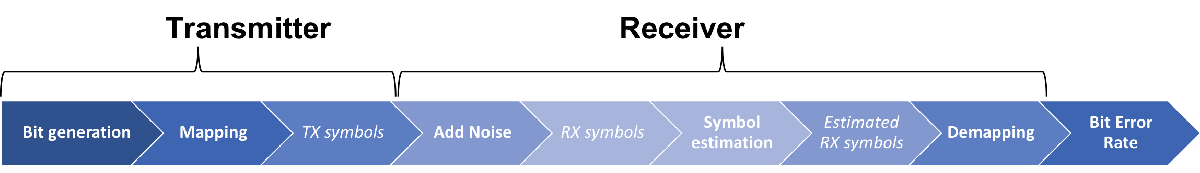

At the transmitter side, the bits to be transmitted are mapped to complex symbols. These symbols are directly transmitted to the receiver (i.e., no pulse shaping, no up-conversion to the carrier frequency). The channel is not considered in this simulation so the only perturbation the transmitted symbols undergo is the thermal noise produced by the receiver electronics. This noise is modeled by a complex Additive White Gaussian Noise (AWGN) ensuring a given Signal-to-Noise (SNR) fixed as an input parameter. The receiver then estimates the received noisy symbols and convert them back to bits (i.e., the demapping). The Bit Error Rate (BER) is eventually determined by comparing the transmitted with the received bits.

clc;                                        % Clear the command window screen
clear all;                                  % Erase all existing variables, functions, and scripts
close all;                                  % Close all figure windows

## Guidelines: what to do?

The goal it to develop the missing code in the following functions:

- mapping_QAM

- symbol_estimation_QAM

- demapping_QAM

The idea is to implement at least the mapping corresponding to QPSK and 16QAM constellations (that is 2 bits per symbol in the first case, and 4 bits per symbol in the second one).

Once the whole code works well, you can implement a *for* loop to assess and plot the behavior of the BER as a function of the SNR. You can compare the BER curve obtained with numerical simulations to the one using analytical formula (already implemented in Matlab).

You can also go further and implement other types of IQ constellations.

**Tips**: 

- At the begining, generate a few symbols only in order to more simply visualize your variables and results

- Later on, be sure to generate enough bits to evaluate low BER. To observe BER of${\textrm{10}}^{-x}$, at least *x* bits are required to have a sufficient chance to observe one erroneous bit (and more than *x* are required to obtain more accurate results).

## Input parameters

nb_bit = 1e6 ;                              % Number of bits to be transmitted                          
nb_bit_per_symb = 2 ;                       % Number of bits per symbol (2 for QPSK, 4 for 16QAM...)
nb_symb = nb_bit / nb_bit_per_symb ;        % Number of transmitted symbols
snr_dB = 15 ;                               % Signal-to-Noise Ratio at RX (in dB)

## Transmitter (TX)

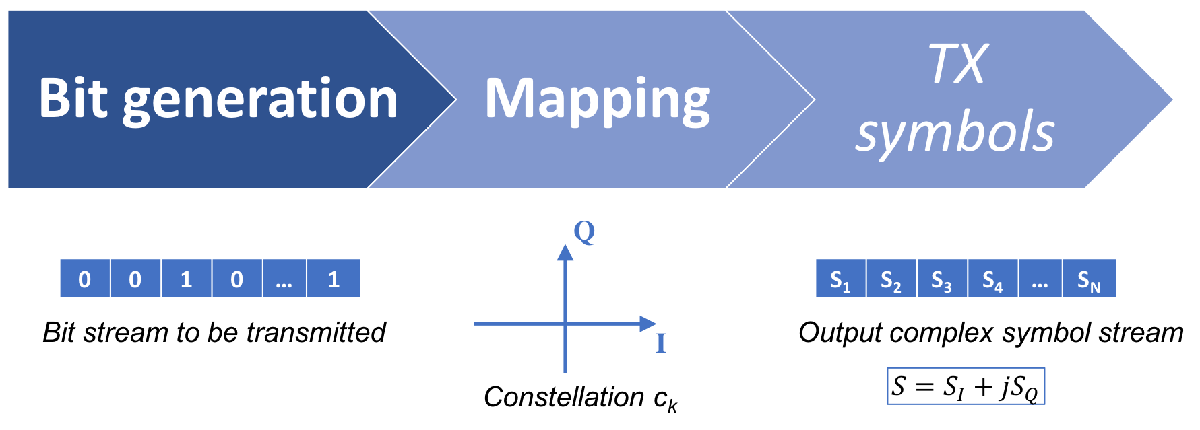

#### Generation of the bits to be transmitted

bit_TX = randi( [0 1] , nb_bit , 1 );                                       % Random bit generation 

#### Creating the symbol stream

symb_TX = mapping_QAM( bit_TX , nb_bit_per_symb , nb_bit ) ;                % Map the input bits to complex symbols

#### Transmitted constellation plot (symbol space)

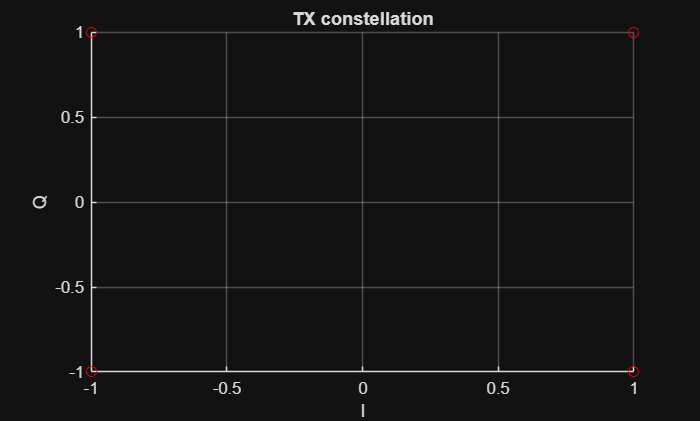

figure
title( 'TX constellation' )
hold on ; grid on ;
plot( real( symb_TX ) , imag( symb_TX ) , 'or' )
xlabel('I')
ylabel('Q')

## Receiver (RX)

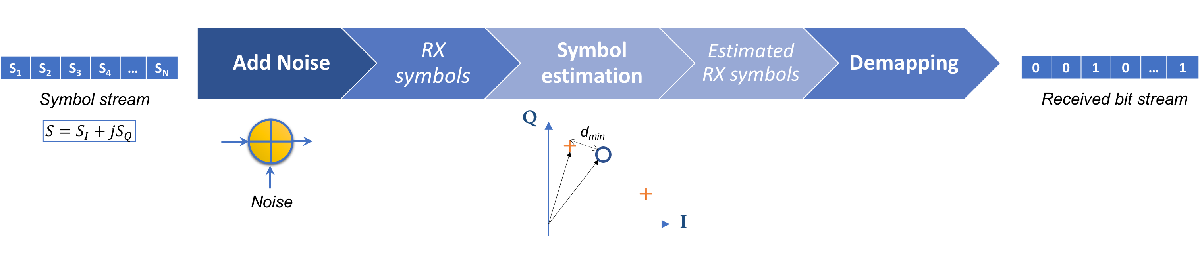

#### Determination of received signal power

rx_mean_power = sum( abs( symb_TX ).^2 , 1 ) / nb_symb ;                        % Calculate the symbols mean power 

#### Creating the RX thermal noise (Complex Additive White Gaussian Noise)

noise = ( randn( nb_symb , 1 ) + 1i * randn( nb_symb , 1 ) ) / sqrt( 2 ) ;      % AWGN with unitary mean power

#### RX signal

snr = 10^( snr_dB / 10 ) ;
symb_RX = symb_TX + noise * sqrt( rx_mean_power / snr ) ;                       % Received signal + thermal noise of receiver hardware

#### Received constellation plot (symbol space)

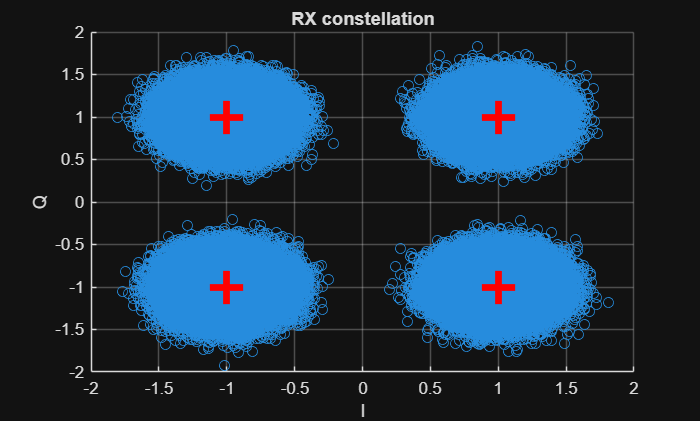

figure
title( 'RX constellation' )
hold on ; grid on ;
plot( real( symb_RX ) , imag( symb_RX ) , 'o')
plot( real( symb_TX ) , imag( symb_TX ) , '+r' , 'MarkerSize' , 20 , 'LineWidth' , 4 )
xlabel('I')
ylabel('Q')

#### Symbol estimation

symb_RX_estimated = symbol_estimation_QAM( symb_RX , nb_bit_per_symb , nb_symb ) ;      % By observing RX symbol, make a decision on which TX symbol has been sent

#### Bit estimation

bit_RX = demapping_QAM( symb_RX_estimated , nb_bit_per_symb , nb_symb ) ;               % Complex-symbols-to-bits demapping

## Bit Error Rate (BER) calculation

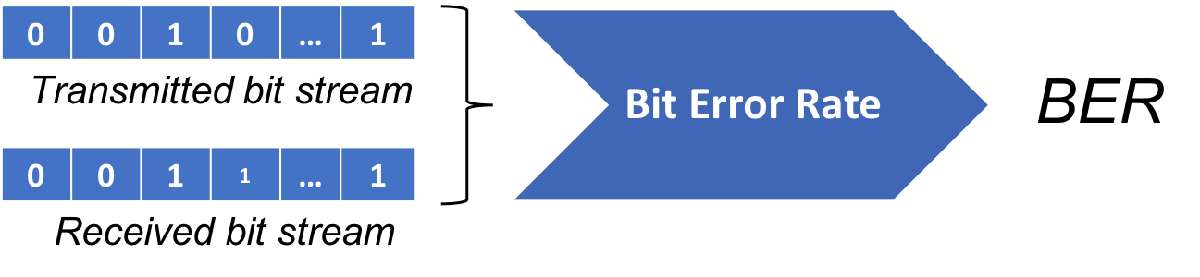

#### Numerical BER calculation

- *nb_error* is the number of errors among the *nb_bit* received bits

- *ber_numerical* is the bit error rate obtained by comparing TX and RX bits

[ nb_error , ber_numerical ] = biterr( bit_TX , bit_RX )

nb_error = 0

ber_numerical = 0

#### Analytical BER calculation

BER analytical expressions exist for some well-known constellations. They can be used to validate your code. Several of those analytical expressions are already implemented in Matlab with the function *berawgn*.

M = 2^nb_bit_per_symb ;                                % Number of symbol values in the constellation
EbNo = snr_dB - 10 * log10 ( nb_bit_per_symb ) ;       % Ratio of bit energy to noise power spectral density, in dB
ber_analytical = berawgn( EbNo , 'qam' , M )           % BER analytical expression for QAM modulation in AWGN channel

ber_analytical = 9.3610e-09

## BER vs SNR — Comparison 4QAM and 16QAM

The following code simulates the BER as a function of the SNR for both 4QAM (QPSK) and 16QAM constellations, and compares with analytical BER expressions.

%% BER vs SNR simulation for 4QAM and 16QAM
nb_bit_sim = 1e6 ;                                      % Number of bits per simulation point
snr_range = 0:2:20 ;                                    % SNR range in dB

modulations = [2, 4] ;                                  % bits per symbol: 2 -> 4QAM, 4 -> 16QAM
colors_sim  = {'bo-', 'rs-'} ;                          % Plot styles for simulation
colors_ana  = {'b--', 'r--'} ;                          % Plot styles for analytical
labels_sim  = {'4QAM (sim)', '16QAM (sim)'} ;
labels_ana  = {'4QAM (analytical)', '16QAM (analytical)'} ;

figure
hold on ; grid on ;

for mod_idx = 1 : length(modulations)

    nb_bps = modulations(mod_idx) ;                     % bits per symbol
    M_mod  = 2^nb_bps ;                                 % Constellation size
    nb_symb_sim = nb_bit_sim / nb_bps ;
    ber_sim = zeros(1, length(snr_range)) ;

    % Generate TX bits and symbols once
    bit_TX_sim  = randi( [0 1] , nb_bit_sim , 1 ) ;
    symb_TX_sim = mapping_QAM( bit_TX_sim , nb_bps , nb_bit_sim ) ;
    rx_power    = sum( abs(symb_TX_sim).^2 ) / nb_symb_sim ;

    for k = 1 : length(snr_range)

        snr_lin = 10^( snr_range(k) / 10 ) ;

        % Generate noise and received signal
        n = ( randn(nb_symb_sim,1) + 1j*randn(nb_symb_sim,1) ) / sqrt(2) ;
        symb_RX_sim = symb_TX_sim + n * sqrt( rx_power / snr_lin ) ;

        % Estimation and demapping
        symb_est = symbol_estimation_QAM( symb_RX_sim , nb_bps , nb_symb_sim ) ;
        bit_RX_sim = demapping_QAM( symb_est , nb_bps , nb_symb_sim ) ;

        % BER calculation
        [ ~ , ber_sim(k) ] = biterr( bit_TX_sim , bit_RX_sim ) ;
    end

    % Plot numerical BER
    semilogy( snr_range , ber_sim , colors_sim{mod_idx} , 'LineWidth' , 1.5 , 'MarkerSize' , 6 )

    % Plot analytical BER
    EbNo_range = snr_range - 10*log10(nb_bps) ;
    ber_ana = berawgn( EbNo_range , 'qam' , M_mod ) ;
    semilogy( snr_range , ber_ana , colors_ana{mod_idx} , 'LineWidth' , 1.5 )

end

xlabel('SNR (dB)')
ylabel('BER')
title('BER vs SNR — 4QAM and 16QAM')
legend( labels_sim{1}, labels_ana{1}, labels_sim{2}, labels_ana{2} , 'Location' , 'southwest' )
ylim([1e-6, 1])